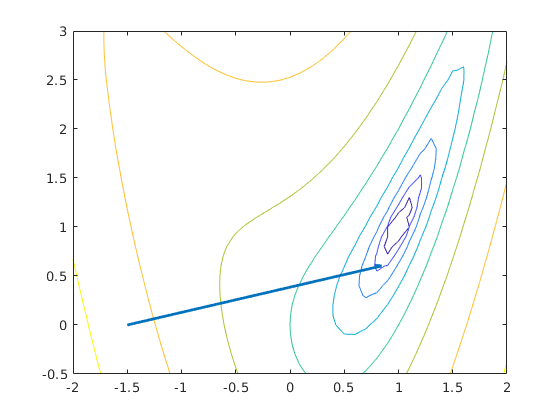

clc;
clear;
close all;

f = @(x1,x2,gamma) gamma*(x1.^2-x2).^2+(x1-1).^2;

g = @(x1,x2,gamma) [4*gamma*x1.*(x1.^2-x2)+2*x1-1; -2*gamma*(x1.^2-x2)];

H = @(x1,x2,gamma) [4*gamma*(x1.^2-x2)+8*gamma*x1.^2+2, -4*gamma*x1;...
                    -4*gamma*x1, 2*gamma];
                
gamma = 1;
v = zeros(1000,2);
v(1,:) = [-1.5,0];
[xx1, xx2] = meshgrid(-2:0.1:2,-0.5:0.1:3);
figure;
contour(xx1,xx2,log(f(xx1,xx2,gamma)));
hold on;
for n=1:999
    % steepest descent with exact line search
    pk = -g(v(n,1),v(n,2),gamma);
    fes = @(a) f(v(n,1)+a*pk(1),v(n,2)+a*pk(2),gamma);
    alpha = fminbnd(fes,1e-10,1);
    v(n+1,:) = v(n,:) + (alpha*pk)';
end
plot(v(:,1),v(:,2),'LineWidth',2);
hold off;

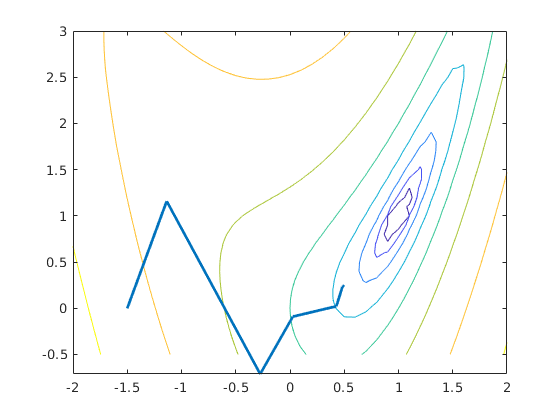

    
gamma = 1;
v = zeros(1000,2);
v(1,:) = [-1.5,0];
[xx1, xx2] = meshgrid(-2:0.1:2,-0.5:0.1:3);
figure;
contour(xx1,xx2,log(f(xx1,xx2,gamma)));
hold on;
for n=1:999
    % Newton's method with exact line search
    pk = -H(v(n,1),v(n,2),gamma)\g(v(n,1),v(n,2),gamma);
    fes = @(a) f(v(n,1)+a*pk(1),v(n,2)+a*pk(2),gamma);
    alpha = fminbnd(fes,1e-10,1);
    v(n+1,:) = v(n,:) + (alpha*pk)';
end
plot(v(:,1),v(:,2),'LineWidth',2);
hold off;

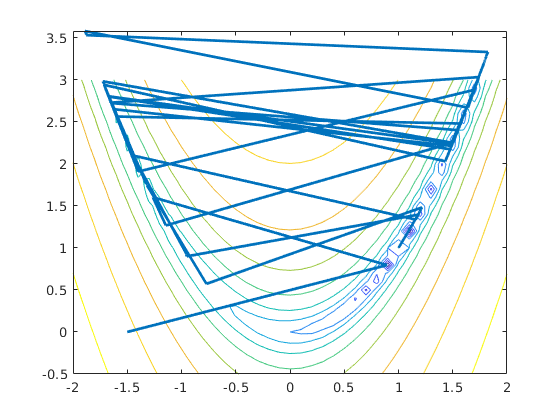


gamma = 100;
v = zeros(1000,2);
v(1,:) = [-1.5,0];
[xx1, xx2] = meshgrid(-2:0.1:2,-0.5:0.1:3);
figure;
contour(xx1,xx2,log(f(xx1,xx2,gamma)));
hold on;
for n=1:999
    % steepest descent with exact line search
    pk = -g(v(n,1),v(n,2),gamma);
    fes = @(a) f(v(n,1)+a*pk(1),v(n,2)+a*pk(2),gamma);
    alpha = fminbnd(fes,1e-10,1);
    v(n+1,:) = v(n,:) + (alpha*pk)';
end
plot(v(:,1),v(:,2),'LineWidth',2);
hold off;

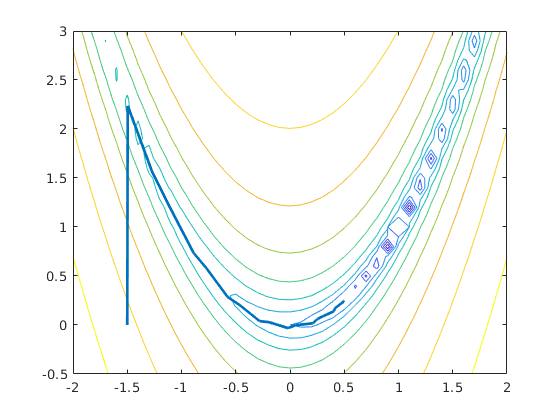

    
gamma = 100;
v = zeros(1000,2);
v(1,:) = [-1.5,0];
[xx1, xx2] = meshgrid(-2:0.1:2,-0.5:0.1:3);
figure;
contour(xx1,xx2,log(f(xx1,xx2,gamma)));
hold on;
for n=1:999
    % Newton's method with exact line search
    pk = -H(v(n,1),v(n,2),gamma)\g(v(n,1),v(n,2),gamma);
    fes = @(a) f(v(n,1)+a*pk(1),v(n,2)+a*pk(2),gamma);
    alpha = fminbnd(fes,1e-10,1);
    v(n+1,:) = v(n,:) + (alpha*pk)';
end
plot(v(:,1),v(:,2),'LineWidth',2);
hold off;